# Data Analytics - Load Forecasting Case Study

## Load messy data

Our raw NYISO data is in a format that is not ideal for analysis and contains multiple anomalies in the data that need cleaning.

load load_forecasting_data.mat
head(nyisoRaw)

         TimeStamp            Name        Load 
    ___________________    __________    ______

    10/01/2019 00:00:00    {'CAPITL'}    1163.9
    10/01/2019 00:00:00    {'CENTRL'}    1425.5
    10/01/2019 00:00:00    {'DUNWOD'}     542.3
    10/01/2019 00:00:00    {'GENESE'}     920.5
    10/01/2019 00:00:00    {'HUD VL'}     865.3
    10/01/2019 00:00:00    {'LONGIL'}    1898.8
    10/01/2019 00:00:00    {'MHK VL'}     664.1
    10/01/2019 00:00:00    {'MILLWD'}       247



## Compute grouped summary statistics

Computing summary statistics by region can help identify some anomalies in the data. We can see that all regions have the same number of readings, and some missing values. The range of values are within an order of magnitude of each other.

% Compute group summary
gc = groupsummary(nyisoRaw,"TimeStamp",10)

gc = 10x2 table
          disc_TimeStamp          GroupCount
    __________________________    __________

    [27-Sep-2019, 07-Oct-2019)      19437   
    [07-Oct-2019, 17-Oct-2019)      32021   
    [17-Oct-2019, 27-Oct-2019)      32406   
    [27-Oct-2019, 06-Nov-2019)      32285   
    [06-Nov-2019, 16-Nov-2019)      32175   
    [16-Nov-2019, 26-Nov-2019)      32263   
    [26-Nov-2019, 06-Dec-2019)      31988   
    [06-Dec-2019, 16-Dec-2019)      31834   
    [16-Dec-2019, 26-Dec-2019)      32032   
    [26-Dec-2019, 05-Jan-2020)      19415   


## Reformat the timetable

It is easier to analyze signals when they are each in their own column. Use the Unstack Live Task to reformat the table.

% Unstack variables
nyiso = unstack(nyisoRaw,"Load","Name","AggregationFunction",@mean,...
    "VariableNamingRule","preserve")

nyiso = 26884x11 timetable
         TimeStamp         CAPITL    CENTRL    DUNWOD    GENESE    HUD VL    LONGIL    MHK VL    MILLWD    N.Y.C.    NORTH     WEST 
    ___________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    _____    ______

    10/01/2019 00:00:00    1163.9    1425.5    542.3     920.5     865.3     1898.8    664.1       247     5011.9    439.1    1498.7
    10/01/2019 00:05:00    1156.7    1421.3    528.8     923.9     851.5     1888.5      683     259.2     4998.4    436.8    1481.

## Missing data

We've identified that all our regions contain some missing data. Let's identify them and interpolate the missing values.

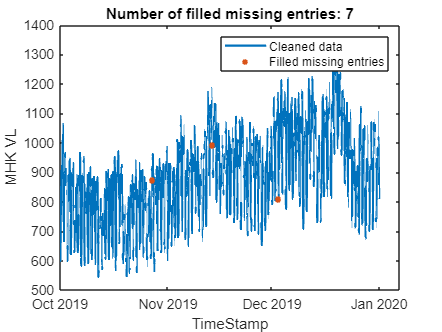

% Fill missing data
[nyisoMissing,missingIndices] = fillmissing(nyiso,"linear");

% Display results
figure

% Plot cleaned data
plot(nyiso.TimeStamp,nyisoMissing.("MHK VL"),"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(nyiso.TimeStamp(missingIndices(:,7)),nyisoMissing.("MHK VL")(missingIndices(:,7)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,...
    "DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,7)))

hold off
legend
ylabel("MHK VL")
xlabel("TimeStamp")

clear missingIndices

## Outliers

We know our signals contain spikey outliers, let's find a way to clean them.

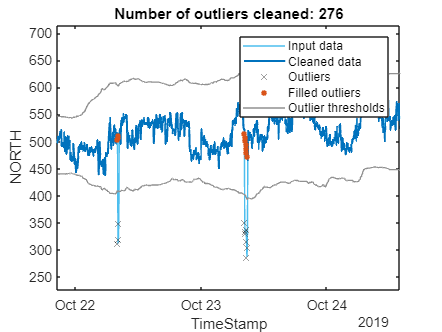

% Fill outliers
[nyisoOutliers,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(nyisoMissing,"linear","movmedian",hours(24));

% Display results
clf
plot(nyisoMissing.TimeStamp,nyisoMissing.NORTH,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(nyisoMissing.TimeStamp,nyisoOutliers.NORTH,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(nyisoMissing.TimeStamp(outlierIndices(:,10)),nyisoMissing.NORTH(outlierIndices(:,10)),...
    "x","Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers cleaned: " + nnz(outlierIndices(:,10)))

% Plot filled outliers
plot(nyisoMissing.TimeStamp(outlierIndices(:,10)),nyisoOutliers.NORTH(outlierIndices(:,10)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([nyisoMissing.TimeStamp(:); missing; nyisoMissing.TimeStamp(:)],...
    [thresholdHigh.NORTH(:); missing; thresholdLow.NORTH(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
ylabel("NORTH")
xlabel("TimeStamp")
clear outlierIndices thresholdLow thresholdHigh
xlim([datetime(2019,10,21,20,32,52)...
      datetime(2019,10,24,13,55,40)])
ylim([226 715])

## Smoothing

Some regions have noise that would be easier to analyze if smoothed.

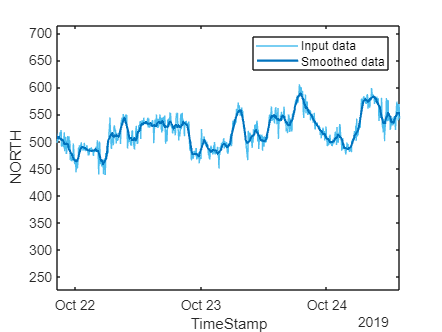

% Smooth input data
nyisoSmooth = smoothdata(nyisoOutliers,"movmean",hours(1));

% Display results
clf
plot(nyisoOutliers.TimeStamp,nyisoOutliers.NORTH,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(nyisoOutliers.TimeStamp,nyisoSmooth.NORTH,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
legend
ylabel("NORTH")
xlabel("TimeStamp")
xlim([datetime(2019,10,21,20,32,52)...
      datetime(2019,10,24,13,55,40)])
ylim([226 715])

## Extract data from a particular region

time = datenum(nyisoSmooth.TimeStamp);
loadArray = nyisoSmooth.CAPITL;